clear; clc; close all force
% change directory in order for relative references to work
cd(fileparts(matlab.desktop.editor.getActiveFilename))

# Part I: Machine learning

The goal of this notebook is to familiarize you with the machine learning process in Matlab. You will make use of this toolbox next year as well. The required datasets are avaible from within Matlab or will be availble for download on BelADL in the course's repository. The overal workflow in machine learning can be described as follows:

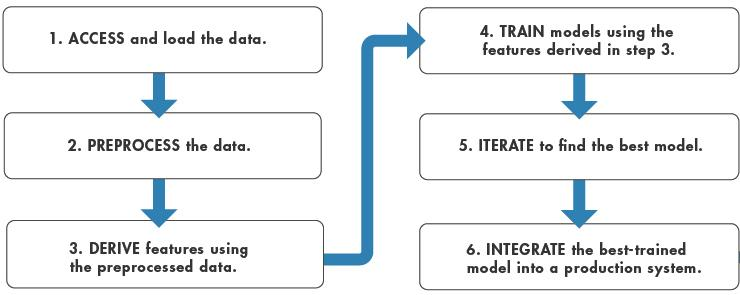

Obtaining clean data is often a time-consuming activity. Be aware that in practice you will rarely be confronted with data that you can immediately use in a model. Data transformation and purification skills are indispensable in practice, as you might discover when working on your project.

Most machine learning frameworks work in a similar way: there are umbrella functions that allow you to train a chosen model and assess its quality via a chosen metric. One of the advantages of the Matlab environment is that there are also several modules that allow you to experiment in a graphical environment.

# Decision trees

## Application 1 (18.5)

Suppose somebody has generated a decision tree (without specifying in what way it was created). Based on this tree, we generate a training set. This training set is then used to train a decision tree using the decision-tree learning algorithm. Is it the case that the learning algorithm will eventually return the correct tree as the training-set size goes to infinity? Why or why not?

## Application 2 (18.8)

Consider the following dataset comprised of three binary inputs $A_1,A_2, A_3$. Use the decision-tree learning algorithm to learn a decision tree for the data. Show the computations made to determine the attribute to split at each node. Use both entropy and information gain as importance function. Remember that the information gain of a split is given by:


$$GAIN(split) = H_{\text{parent}} - H_{\text{remainders, split}}$$



$$Gain(split) = 
H_{\text{parent}} - \sum_{j=1}^{k}\frac{n_j}{n}H_j$$


where $H_j=\sum_{i}^{} \left( -p(i|j) \log_{2}p(i|j) \right)$ and $p(i|j)$ is the ratio of the number of observations of class $i$ and the total number of observations in node $j$.

T = table([1;1;0;1;1], [0;0;1;1;1],[0;1;0;1;1],[0;0;0;1;1], ...
    'VariableNames',{'A1','A2','A3','Label'}, ...
    'RowNames',{'x1','x2','x3','x4','x5'});
T.Properties.Description = 'Entropy and information gain';
T

T = 5×4 table
          A1    A2    A3    Label
          __    __    __    _____

    x1    1     0     0       0  
    x2    1     0     1       0  
    x3    0     1     0       0  
    x4    1     1     1       1  
    x5    1     1     1       1  


p_0_r = 3/5; p_1_r = 2/5;
H_root = - (p_0_r*log2(p_0_r) + p_1_r*log2(p_1_r));
% split on A_1:
p_0_H1 = 1; p_1_H1 = 0;
H_1 = -(p_0_H1*log2(p_0_H1)); %+ p_1_H1*log2(p_1_H1));
p_0_H2 = 1/2; p_1_H2 = 1/2;
H_2 = -(p_0_H2*log2(p_0_H2) + p_1_H2*log2(p_1_H2));
% gain:
H_root - (1/5*H_1 + 4/5*H_2)

ans = 0.1710

Information gain is not the only possibility to split a decision tree, other methods exist:

- gain ratio: ratio of the information gain by the intrinsic information

- gini index (or gini impurity):  measures the degree or probability of a particular variable being wrongly classified when it is randomly chosen. The feature with the lowest Gini index after a split is selected as the splitting feature.


$$GINI(split)=\sum_{j=1}^{k}\frac{n_{j}}{n}GINI(j)$$


where $GINI(j) = 1- \sum_{i}^{}\left[p(i|j)\right]^{2}$ and where $p(i|t)$ is the ratio of the number of observations of class i and the total number of observations in node j.

## Application 3 

We will use a decision tree to see if we can predict the outcome of the Titanic disaster based on a number of features. We load up the data from a CSV file. Matlab's readtable function can be used for this. Also note that

- the appropriate datatype is infered from the CSV file.

- If required, appropriate missing values (a `NaN` value for numeric variables, and an empty character vector for text) are added automatically.

% Load the data (Matlab path should be the location of the file for this to work)
d = readtable('./datasets/titanic.csv')

d = 887×8 table
    Survived    Pclass                             Name                                Sex        Age    Siblings_SpousesAboard    Parents_ChildrenAboard     Fare 
    ________    ______    ______________________________________________________    __________    ___    ______________________    ______________________    ______

       0          3       {'Mr. Owen Harris Braund'                            }    {'male'  }    22               1                         0                 7.25
       1          1       {'Mrs. John Bradley (Florence Briggs Thayer) Cumings'}    {'female'}    38               1                         0               71.283
       1          3       {'Miss. Laina Heikkinen'     

When we just import the data like it is, notice the following:

- Columns headers are adapted to use proper naming conventions

- Some datatypes are inferred from the file, you can verify this by right-clicking on a column. You will also see some options to convert data

%% specify some details about the features:
% Make categorical data where appropriate
d.Pclass = categorical(d.Pclass);
d.Sex = categorical(d.Sex);
% Make categorical and add labels => increase readability
d.Survived = categorical(d.Survived,[0 1],{'No' 'Yes'})

d = 887×8 table
    Survived    Pclass                             Name                              Sex      Age    Siblings_SpousesAboard    Parents_ChildrenAboard     Fare 
    ________    ______    ______________________________________________________    ______    ___    ______________________    ______________________    ______

      No          3       {'Mr. Owen Harris Braund'                            }    male      22               1                         0                 7.25
      Yes         1       {'Mrs. John Bradley (Florence Briggs Thayer) Cumings'}    female    38               1                         0               71.283
      Yes         3       {'Miss. Laina Heikkinen'                     

The column ‘Survived’ will be the one we want to predict. The other variable names are self-explanatory. Do you think all variables are suited to make a prediction? 

All the implementations of decision trees in Matlab are binary trees, i.e. each step in a prediction involves checking the value of one predictor that is split in two. Matlab includes two types of trees:

- Classification trees: when the outcome is nominal (i.e. a class such as dead or alive in our case)

- Regression trees: when the outcome is numerical. 

You can choose to build your decision tree model by using pure code (as shown below), or by using the ‘Classification Learner’ module from the included Matlab Apps. The module has the added advantage that you can experiment freely and keep track of different iterations of your models (and their performance). Additionally, you have visual tools such as the confusion matrix and ROC curve readily at hand. All these tools are available in other ML frameworks as well, but they would require some more effort from the user to generate these results.

% build tree on the table using the data and selected fields
tree = fitctree(d, "Survived",...
                    'PredictorNames',{'Pclass','Sex','Fare','Age',...
                                      'Parents_ChildrenAboard','Siblings_SpousesAboard'})

tree =   ClassificationTree
           PredictorNames: {'Pclass'  'Sex'  'Fare'  'Age'  'Parents_ChildrenAboard'  'Siblings_SpousesAboard'}
             ResponseName: 'Survived'
    CategoricalPredictors: [1 2]
               ClassNames: [No    Yes]
           ScoreTransform: 'none'
          NumObservations: 887


  Properties, Methods


view(tree) % textual description

Decision tree for classification
  1  if Sex=female then node 2 elseif Sex=male then node 3 else No
  2  if Pclass in {1 2} then node 4 elseif Pclass=3 then node 5 else Yes
  3  if Age<13 then node 6 elseif Age>=13 then node 7 else No
  4  if Age<2.5 then node 8 elseif Age>=2.5 then node 9 else Yes
  5  if Fare<23.35 then node 10 elseif Fare>=23.35 then node 11 else No
  6  if Siblings_SpousesAboard<2.5 then node 12 elseif Siblings_SpousesAboard>=2.5 then node 13 else Yes
  7  if Fare<26.2688 then node 14 elseif Fare>=26.2688 then node 15 else No
  8  class = No
  9  if Fare<28.8562 then node 16 elseif Fare>=28.8562 then node 17 else Yes
 10  if Age<36.5 then node 18 elseif Age>=36.5 then node 19 else Yes
 11  if Parents_ChildrenAboard<0.5 then node 20 elseif Parents_ChildrenAboard>=0.5 then node 21 else No
 12  class = Yes
 13  class = No
 14  if Age<32.5 then node 22 elseif Age>=32.5 then node 23 else No
 15  if Fare<26.4688 then node 24 elseif Fare>=26.4688 then node 25 else No
 16 

Note that this tree is highly detailed. This due to several settings such as:

- the number of features used

- the maximal depth of the three

- minimum amount of samples per node

- minimum amount of samples to allow a split

- the minimum increase in purity after a split

- minimal pruning purity

If we impose a minimum leaf size of 20, we obtain something more readable:

% limited tree
lim_tree = fitctree(d, "Survived",...
                    'PredictorNames',{'Pclass','Sex','Fare','Age',...
                                      'Parents_ChildrenAboard','Siblings_SpousesAboard'},...
                     "MinLeafSize",20)

lim_tree =   ClassificationTree
           PredictorNames: {'Pclass'  'Sex'  'Fare'  'Age'  'Parents_ChildrenAboard'  'Siblings_SpousesAboard'}
             ResponseName: 'Survived'
    CategoricalPredictors: [1 2]
               ClassNames: [No    Yes]
           ScoreTransform: 'none'
          NumObservations: 887


  Properties, Methods


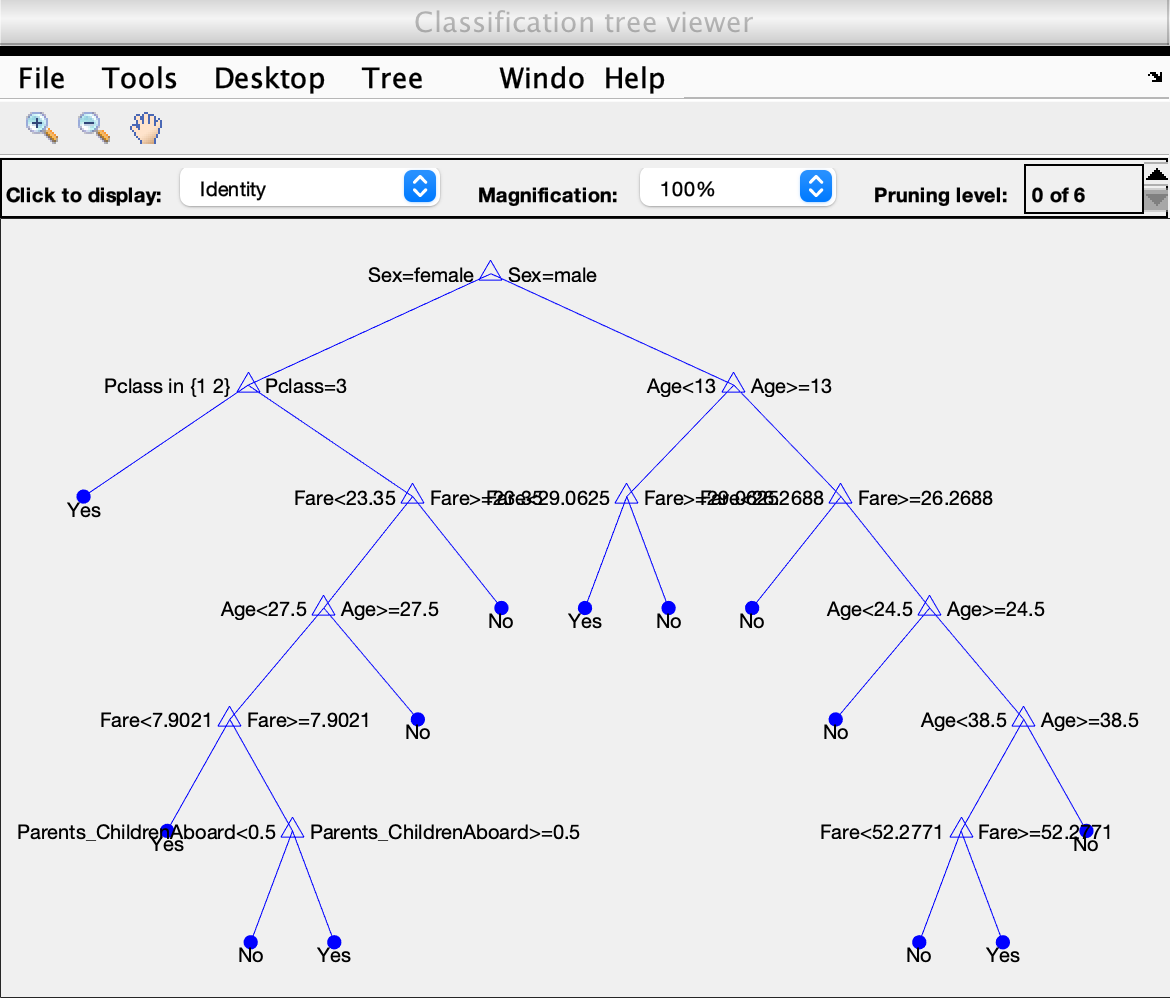

% quick look at the tree
view(lim_tree,'Mode',"graph")

Different performance metrics exist to evaluate the quality of a model.

% Some performance metrics:
loss(lim_tree,d, d.Survived) % amount of wrong classifications

ans = 0.1601

% probabilities for each class from the training data:
[preds,probs] = resubPredict(lim_tree);

% confusion matrix (in counts)
cm = confusionmat(d.Survived, preds) 

cm =    510    35
   107   235


confusionchart(cm, {'dead','alive'})

% ROC curve
[Xnb,Ynb,T,AUC] = perfcurve(d.Survived, probs(:,lim_tree.ClassNames(2)), 'Yes');
plot(Xnb,Ynb)
title('Tree ROC curve')
xlabel('False positive rate'); 
ylabel(sprintf('True positive rate'));

Note that up to now we have used all of the data. In order to avoid this and to be able to get an idea of the performance of our model on unknown data, we use a cross validation.

% 7-fold cross validation on limited tree
cv_lim_tree = fitctree(d, 'Survived',...
                    'PredictorNames',{'Pclass','Sex','Fare','Age',...
                                      'Parents_ChildrenAboard','Siblings_SpousesAboard'},...
                     "MinLeafSize",20, ...
                     "KFold",7)

cv_lim_tree =   ClassificationPartitionedModel
      CrossValidatedModel: 'Tree'
           PredictorNames: {'Pclass'  'Sex'  'Fare'  'Age'  'Parents_ChildrenAboard'  'Siblings_SpousesAboard'}
    CategoricalPredictors: [1 2]
             ResponseName: 'Survived'
          NumObservations: 887
                    KFold: 7
                Partition: [1×1 cvpartition]
               ClassNames: [No    Yes]
           ScoreTransform: 'none'


  Properties, Methods


cv_lim_tree.kfoldLoss()

ans = 0.2142

#### Further exploration:

- Can you come up with additional features we could extract or generate from the data?

- Do these features provide additional predictive value?

- Can you use the optimization options to try and increase the performance of the tree?

- Try out the different options in the classification viewer such as pruning, and displaying class membership in different ways.

## Application 4 - Tree limitations

Consider the data below and explain the result when fitting a decision tree. Propose a solution and show that the tree works as intended afterwards.

% Set random seed for reproducibility
rng(172)
X = rand(1000,2)*14 - 7;
y = randvals(X);
Y = categorical(y,[1 2 3],{'Cat A', 'Cat B', 'Cat C'});
scatter(X(:,1), X(:,2),5,y);
title('Data plot');

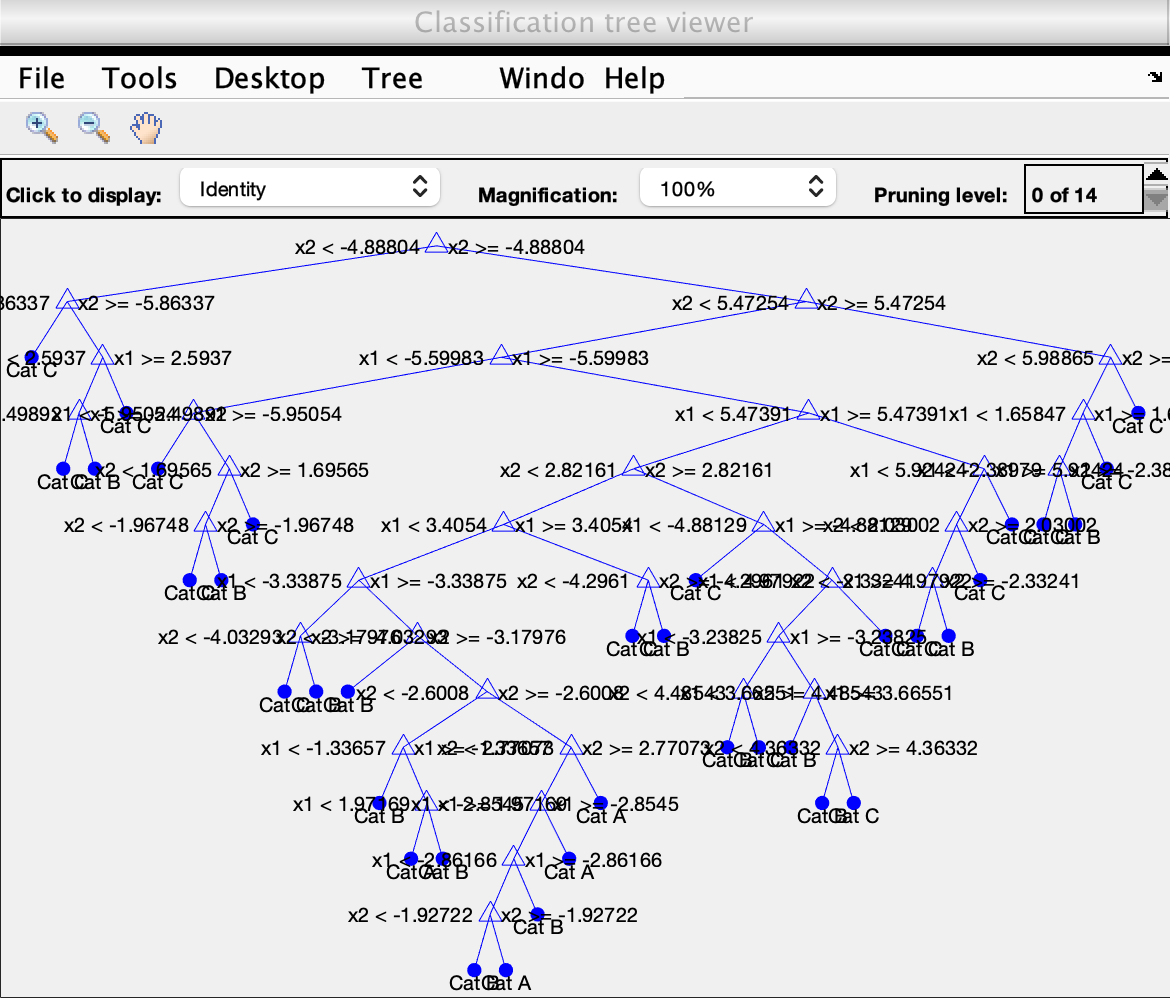

mtree = fitctree(X,Y);
view(mtree,'Mode',"graph")

loss(mtree, X, Y)

ans = 0.0140

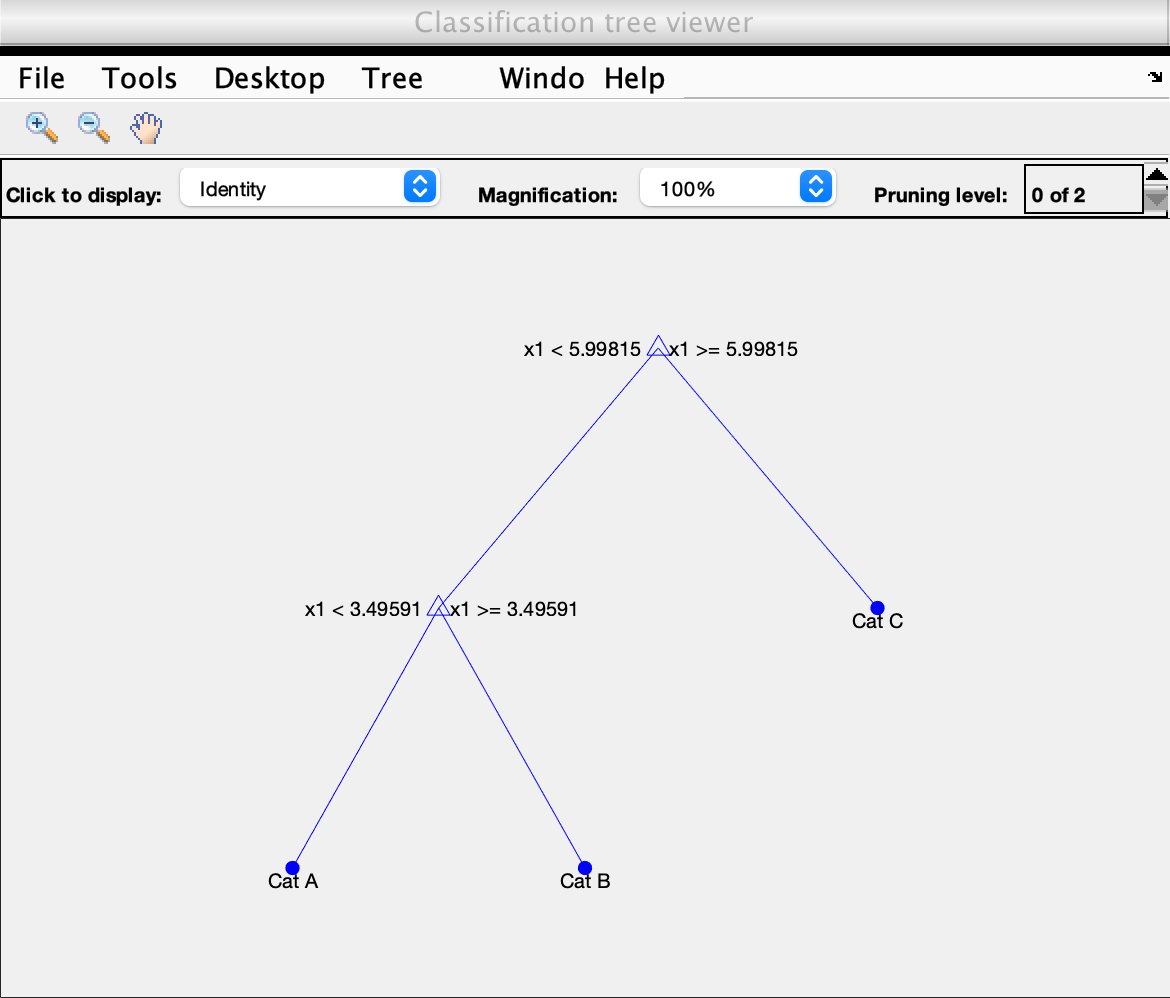

r = sqrt(X(:,1).^2 + X(:,2).^2);
bettertree = fitctree(r,Y);
view(bettertree,'Mode',"graph")

loss(bettertree, r, Y)

ans = 0

## Application 5 - Heart attacks

The dataset below contains information about the risk of having a heart attack. Experiment with decision trees in order to make a good predicton. 

The colum names match as shown below:

- Sex : Sex of the patient (0: male, 1: female)

- exang: exercise induced angina (1 = yes; 0 = no)

- ca: number of major vessels (0-3)

- cp : Chest Pain type chest pain type (1: typical angina, 2: atypical angina, 3: non-anginal pain, 4: asymptomatic)

- trtbps : resting blood pressure (in mm Hg)

- chol : cholestoral in mg/dl fetched via BMI sensor

- fbs : (fasting blood sugar > 120 mg/dl) (1 = true; 0 = false)

- rest_ecg : resting electrocardiographic results( 0: normal, 1: having ST-T wave abnormality (T wave inversions and/or ST elevation or depression of > 0.05 mV), 2: showing probable or definite left ventricular hypertrophy by Estes' criteria)

- thalach : maximum heart rate achieved

- target : 0= less chance of heart attack 1= more chance of heart attack

- oldpeak

- slp : unknown

- caa : unknown

- thal : unknown

- output : '0' matches a lower risk of a heart attack whereas '1' matches a higher chance of a heart attack.

To do:

- Prepare the data

- Use decision trees to come up with an adequate result

- Try some form of feature selection in order to only use relevant features

clear; close all force; clc
h = readtable('./datasets/heart.csv')

h = 303×14 table
    age    sex    cp    trtbps    chol    fbs    restecg    thalachh    exng    oldpeak    slp    caa    thall    output
    ___    ___    __    ______    ____    ___    _______    ________    ____    _______    ___    ___    _____    ______

    63      1     3      145      233      1        0         150        0        2.3       0      0       1        1   
    37      1     2      130      250      0        1         187        0        3.5       0      0       2        1   
    41      0     1   

We can find out what features might be more suited for classification by running a chi-square test for dependence. 

idx = fscchi2(h, 'output')

idx =      3    13    12     9    11    10     8     2     1     7     4     5     6


We then build a tree using all features or a subset, but sorted by importance

t_all = fitctree(h(:, [idx(1:end) end]), 'output')

t_all =   ClassificationTree
           PredictorNames: {'cp'  'thall'  'caa'  'exng'  'slp'  'oldpeak'  'thalachh'  'sex'  'age'  'restecg'  'trtbps'  'chol'  'fbs'}
             ResponseName: 'output'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 303


  Properties, Methods


cvloss(t_all)

ans = 0.2409

t_limited = fitctree(h(:, [idx(1:4) end]), 'output')

t_limited =   ClassificationTree
           PredictorNames: {'cp'  'thall'  'caa'  'exng'}
             ResponseName: 'output'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 303


  Properties, Methods


cvloss(t_limited)

ans = 0.1584

We can also a custom criterion such as the accuracy of the classifier as shown below.

% Using proper feature selection
X = h{:,1:end-1};
X = normalize(X,1);
Y = h{:,end};
[fsfor,historyCV] = sequentialfs(@(xt,yt,xte,yte) treeval(xt,yt,xte,yte), X, Y,'options',statset("Display","iter","MaxIter", 20),'nfeatures',13)

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 13, criterion value 0.237624
Step 2, added column 12, criterion value 0.227723
Step 3, added column 9, criterion value 0.171617
Step 4, added column 3, criterion value 0.178218
Step 5, added column 11, criterion value 0.171617
Step 6, added column 7, criterion value 0.171617
Step 7, added column 6, criterion value 0.171617
Step 8, added column 2, criterion value 0.184818
Step 9, added column 8, criterion value 0.207921
Step 10, added column 10, criterion value 0.194719
Step 11, added column 5, criterion value 0.214521
Step 12, added column 1, criterion value 0.221122
Step 13, added column 4, criterion value 0.240924
Final columns included:  all


fsfor = 1×13 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1


historyCV = struct with fields:
      In: [13×13 logical]
    Crit: [0.2376 0.2277 0.1716 0.1782 0.1716 0.1716 0.1716 0.1848 0.2079 0.1947 0.2145 0.2211 0.2409]


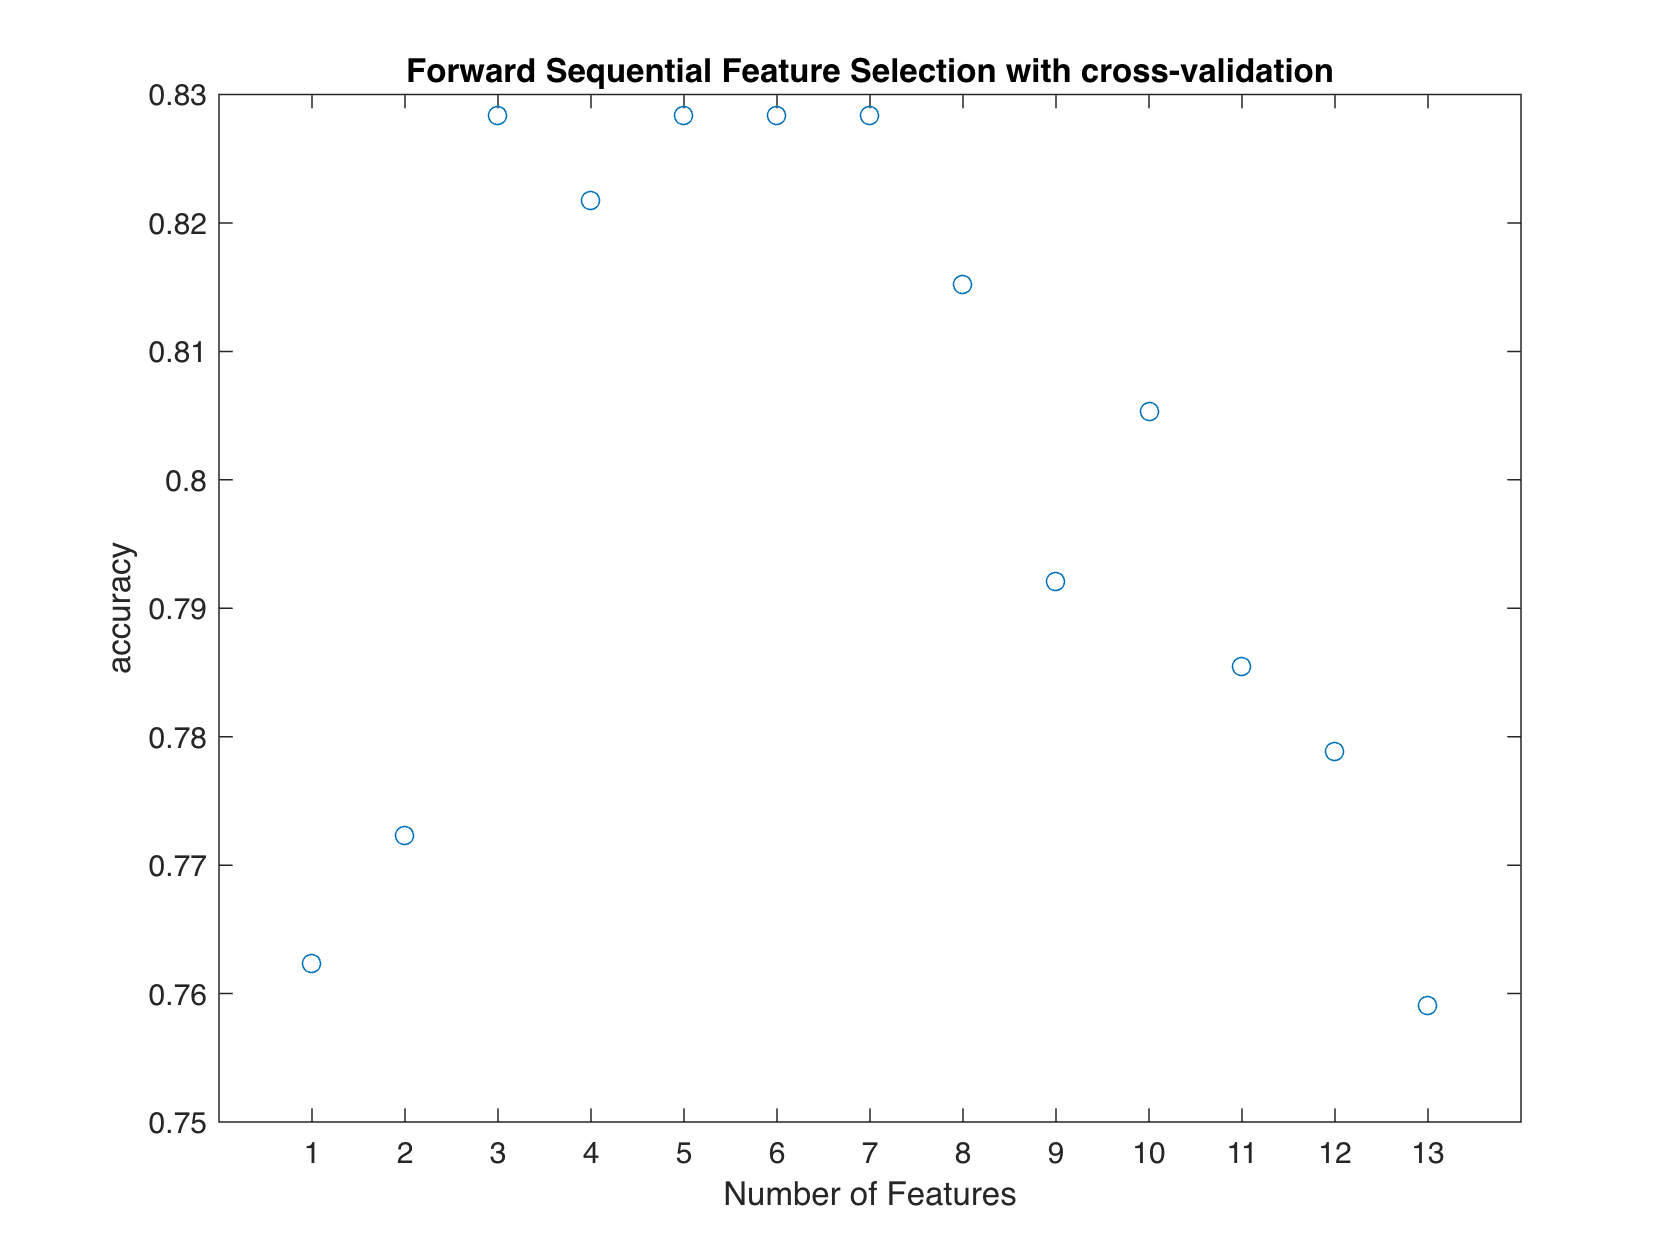

plot(1-historyCV.Crit,'o');
xlabel('Number of Features');
ylabel('accuracy');
xticks(1:length(historyCV.Crit))
title('Forward Sequential Feature Selection with cross-validation');

% Supporting functions

function res = treeval(xtrain,ytrain, xtest, ytest)
    % build model using training data
    model = fitctree(xtrain, ytrain);
    % apply model on testing data
    y_pred = predict(model, xtest);
    % count mismatches
    res = sum(~(y_pred == ytest));
end 

function res = randvals(x)
% RANDVALS generate random data on 2D grid with circular boundaries
    y = zeros(length(x),1);
    for i = 1:length(x)
        if sqrt(x(i,1)^2 + x(i,2)^2) <= 3.5
            y(i) = 1;
        elseif (sqrt(x(i,1)^2 + x(i,2)^2) > 3.5) && (sqrt(x(i,1)^2 + x(i,2)^2) <= 6)
            y(i) = 2;
        else
            y(i) = 3;
        end
    end
    res = y;
end